# Lattice beam

Lattice single beam power (mW), wavelength (um), polarization angle (deg), direction (deg), waist (um)

clear
clc

% Red-detuned circular triangular lattice
LatBeam.Power = [150;150;150];
LatBeam.Wave = 1.064;
LatBeam.Pol = [45,90;45,90;45,90];
LatBeam.Ang = [0,45;120,45;240,45];
LatBeam.Waist = [45,64;45,64;45,64];
LatBeam.Phase = [0;0;0];


XRange = -1:0.02:1;
YRange = -1.5:0.02:1.5;
% XRange = -100:100;
% YRange = -100:100;

XSize = length(XRange);
YSize = length(YRange);

Interference pattern

[Y,X,Z] = meshgrid(0,XRange,YRange);
Intensity = gaussianFull(LatBeam,[X(:),Y(:),Z(:)]);

Unrecognized function or variable 'gaussianFull'.

imagesc(YRange,XRange,reshape(Intensity,XSize,YSize))
colorbar
daspect([1 1 1])
title('Intensity')
xlabel('Z')
ylabel('X')
[Y,X,Z] = meshgrid(YRange,XRange,0);
[Intensity,TotPol,Pol,Dir] = gaussianFull(LatBeam,[X(:),Y(:),Z(:)]);
showPol(Pol,Dir)
figure
imagesc(YRange,XRange,reshape(Intensity,XSize,YSize))
colorbar
daspect([1 1 1])
title('Intensity')
xlabel('Y(\mum)')
ylabel('X(\mum)')

XCenter = 0.26;
YCenter = -0.46;
hold on
scatter(XCenter,YCenter,100,'r',LineWidth=2)
hold off

Static light shift

PotentialStatic = aNLJ('s',6,0,1/2,LatBeam.Wave,'ExpuK')*reshape(Intensity,XSize,YSize);
imagesc(YRange,XRange,PotentialStatic)
colorbar
daspect([1 1 1])
title('Static light shift')

Transition frequency shift

DiffPolarizability = aNLJ('s',6,0,1/2,LatBeam.Wave,'ExpHz')-aNLJ('s',6,1,3/2,LatBeam.Wave,'ExpHz');
TransitionShift = DiffPolarizability*reshape(Intensity,XSize,YSize)*1e-6;
imagesc(YRange,XRange,TransitionShift)
colorbar
daspect([1 1 1])
title('Transition shift (MHz)')

Local polarization decomposition

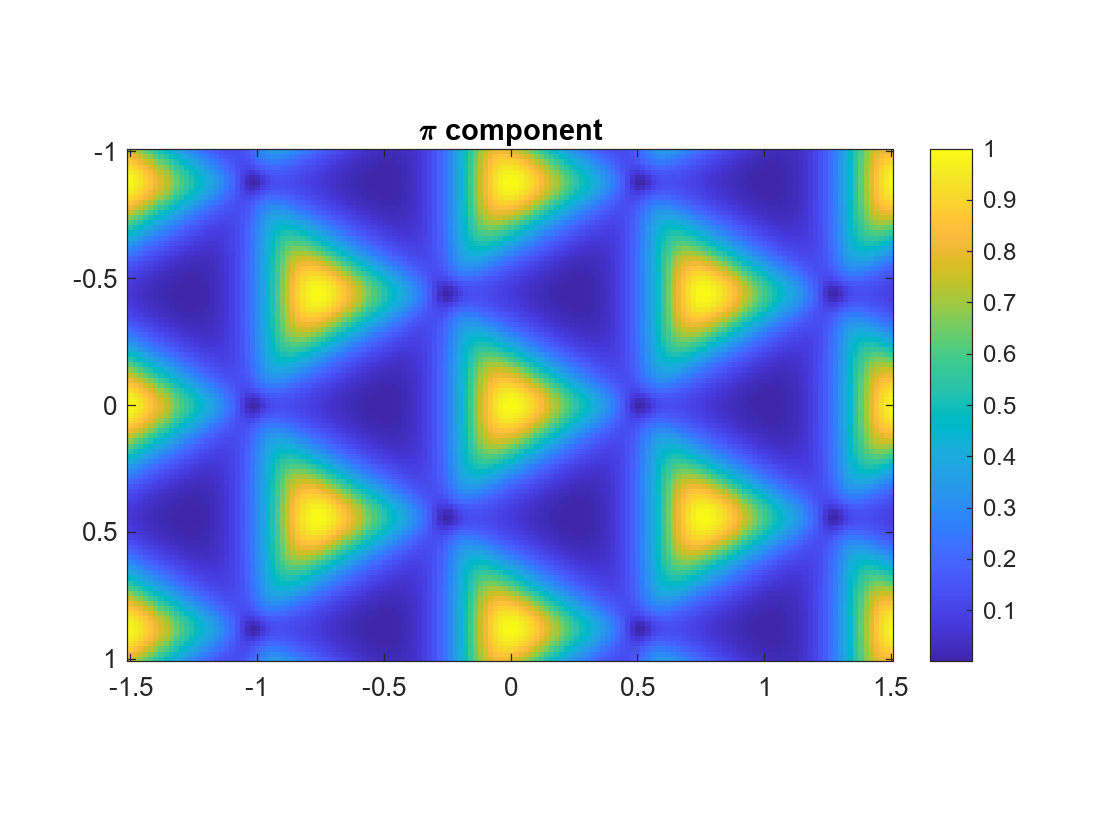

PolCir = decomPol(TotPol,[0,0,1]);
imagesc(YRange,XRange,reshape(abs(PolCir(:,1)).^2,XSize,YSize))
daspect([1 1 1])
colorbar
title('\pi component')

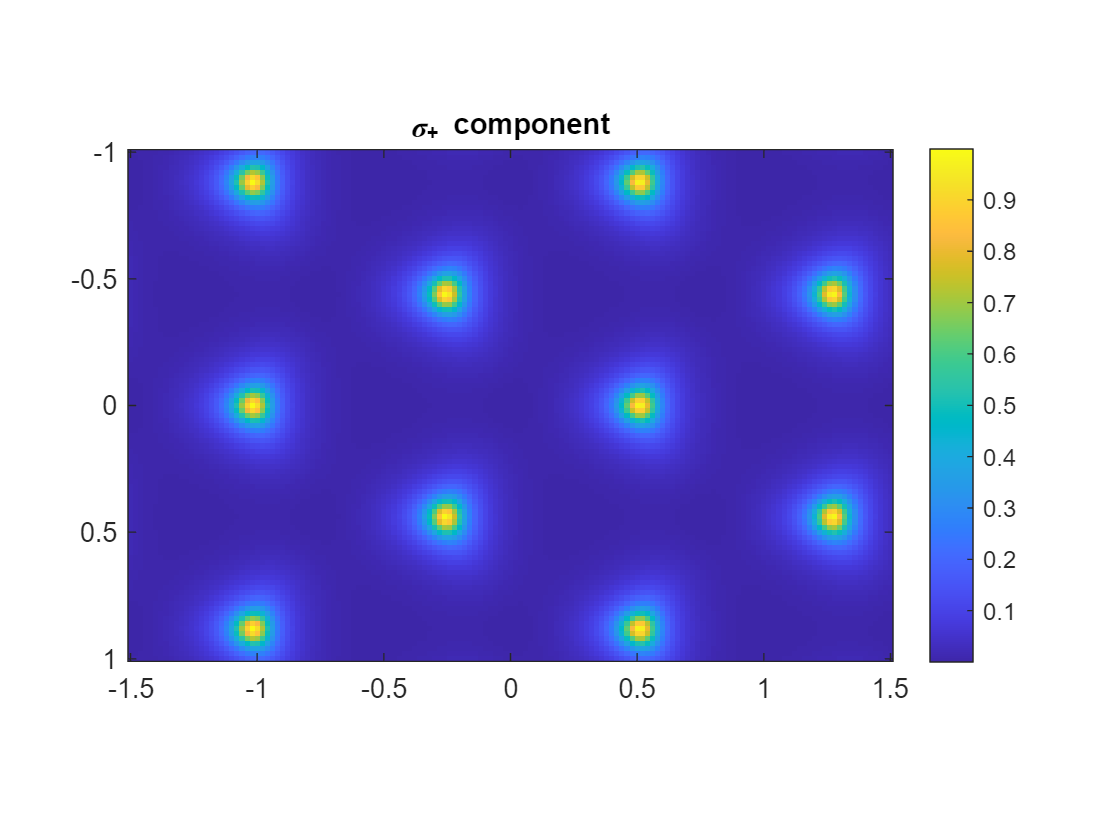

imagesc(YRange,XRange,reshape(abs(PolCir(:,2)).^2,XSize,YSize))
daspect([1 1 1])
colorbar
title('\sigma_+ component')

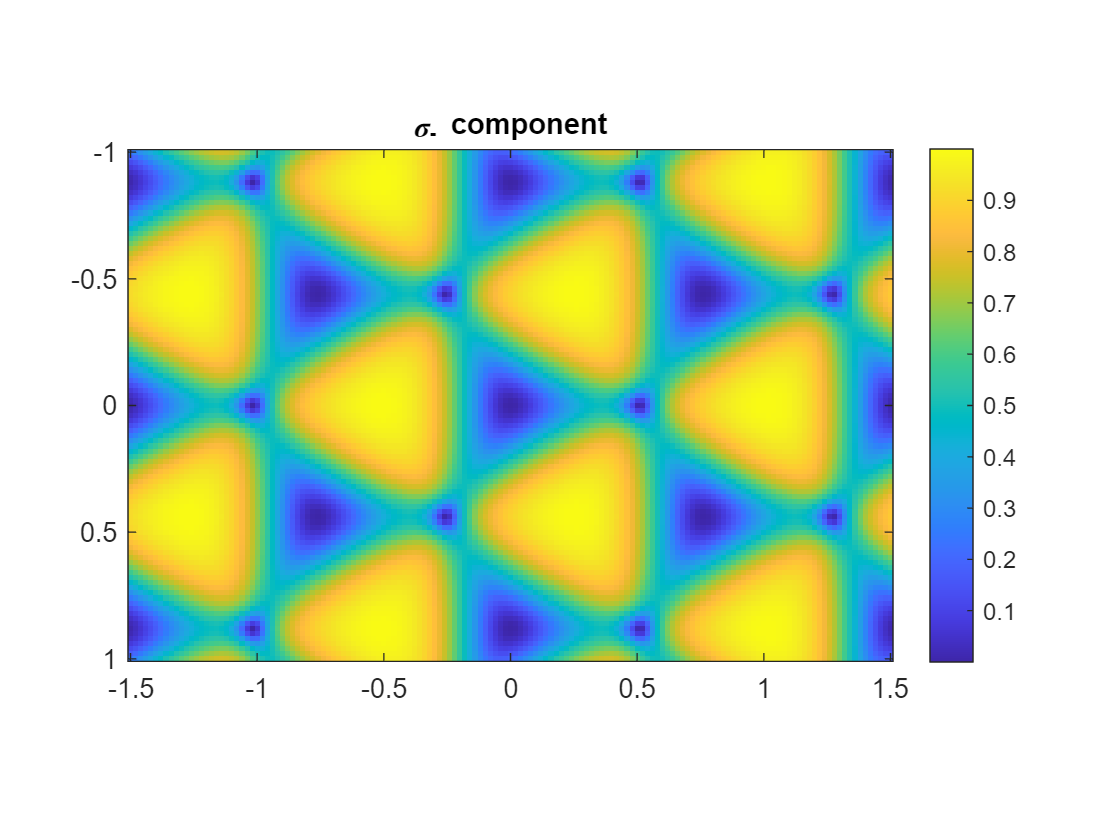

imagesc(YRange,XRange,reshape(abs(PolCir(:,3)).^2,XSize,YSize))
daspect([1 1 1])
colorbar
% caxis([0.9 1])
title('\sigma_- component')

Effective magnetic field

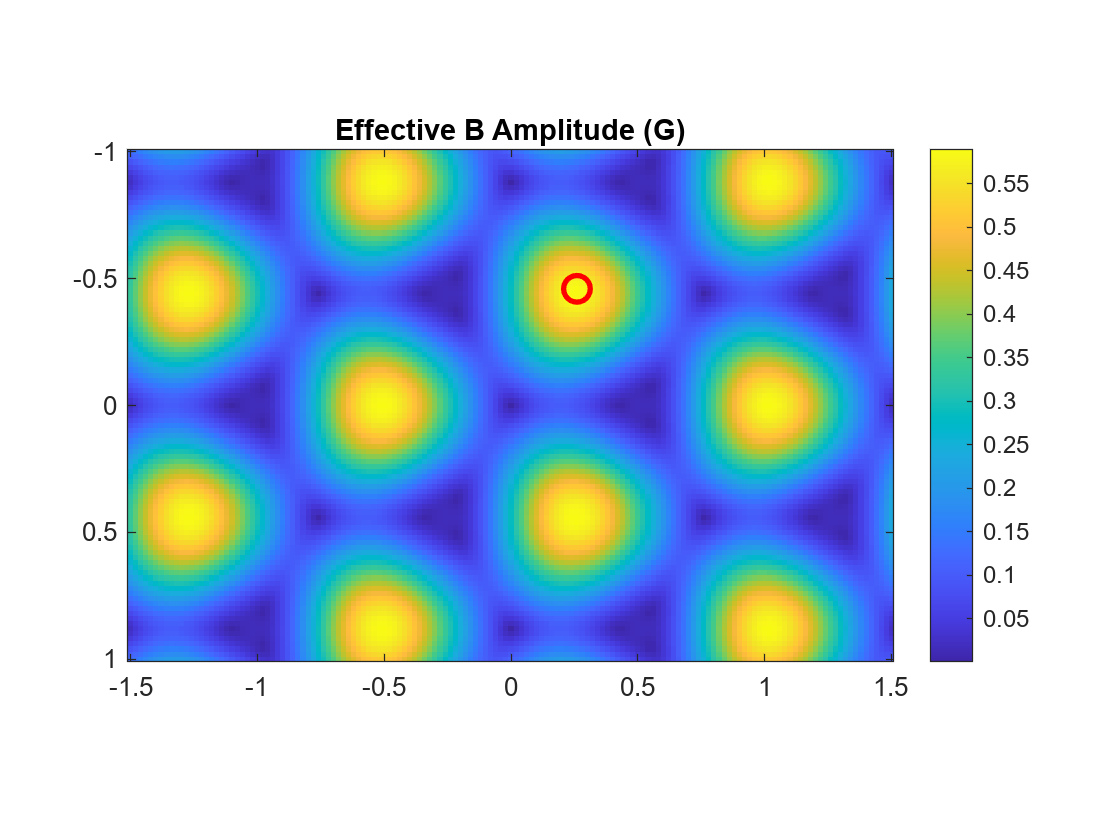

EffB = aNLJ('v',6,0,1/2,LatBeam.Wave,'ExpBFict')*1i*Intensity.*cross(conj(TotPol),TotPol,2);
EffBAmp = reshape(vecnorm(EffB,2,2),XSize,YSize);
EffBDir = reshape(1i*cross(conj(TotPol),TotPol,2),XSize,YSize,3);
EffBAng = zeros(XSize*YSize,2);
[EffBAng(:,1),EffBAng(:,2)] = convertAxis2Ang(1i*cross(conj(TotPol),TotPol,2));
EffBAng = reshape(EffBAng,XSize,YSize,2);
EffBx = reshape(EffB(:,1),XSize,YSize);
EffBy = reshape(EffB(:,2),XSize,YSize);
EffBz = reshape(EffB(:,3),XSize,YSize);

imagesc(YRange,XRange,EffBAmp)
colorbar
daspect([1 1 1])
title('Effective B Amplitude (G)')
hold on
scatter(XCenter,YCenter,100,'r',LineWidth=2)
hold off

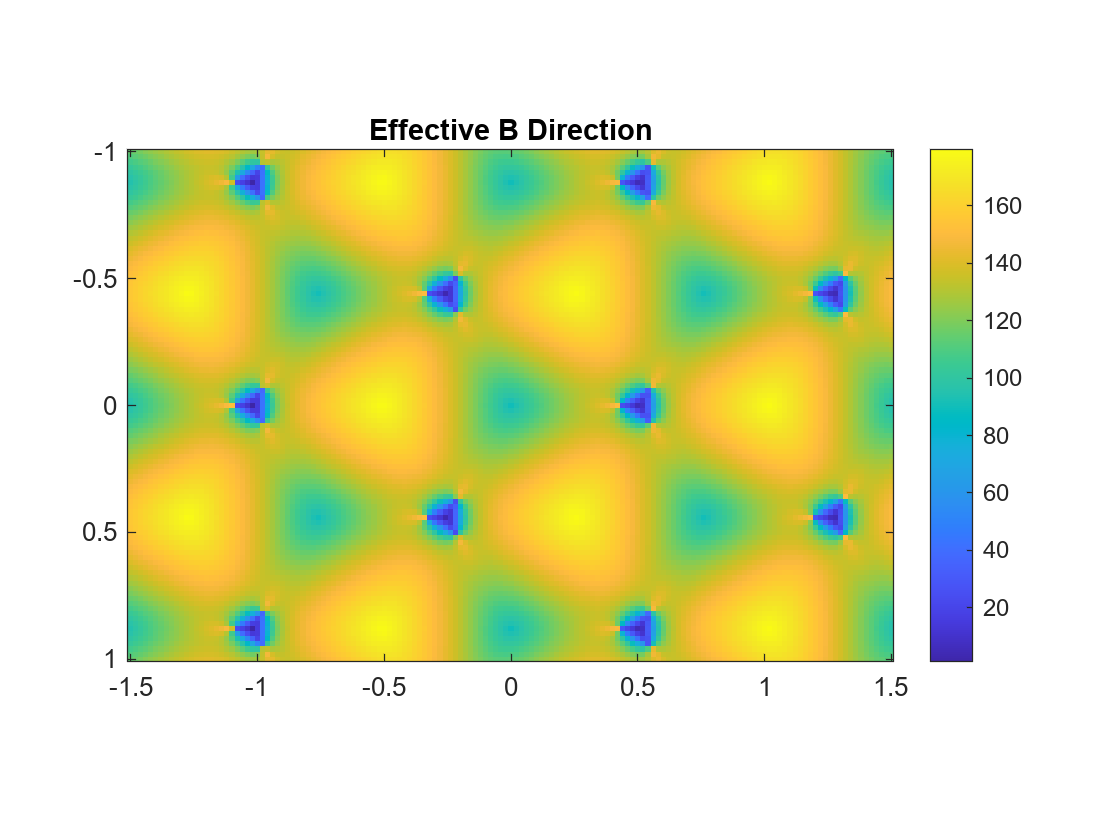


imagesc(YRange,XRange,EffBAng(:,:,2)*180/pi)
colorbar
daspect([1 1 1])
title('Effective B Direction')

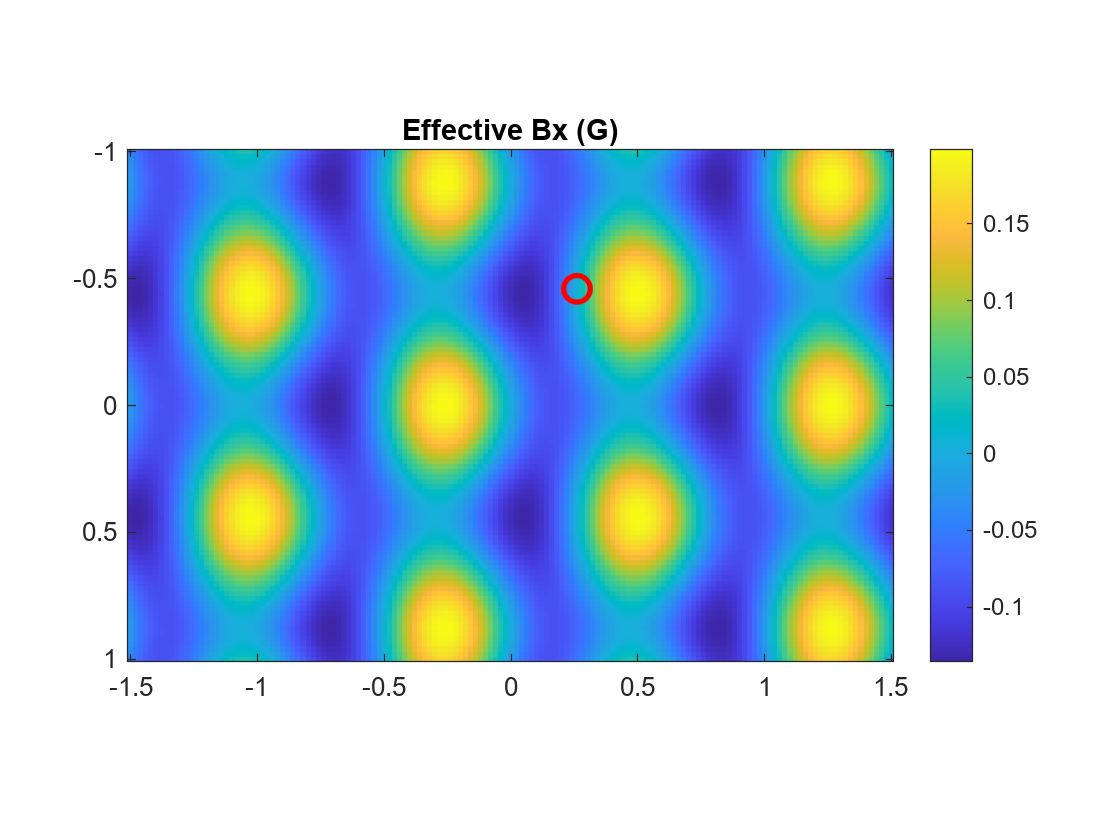


imagesc(YRange,XRange,EffBx)
colorbar
daspect([1 1 1])
title('Effective Bx (G)')
hold on
scatter(XCenter,YCenter,100,'r',LineWidth=2)
hold off

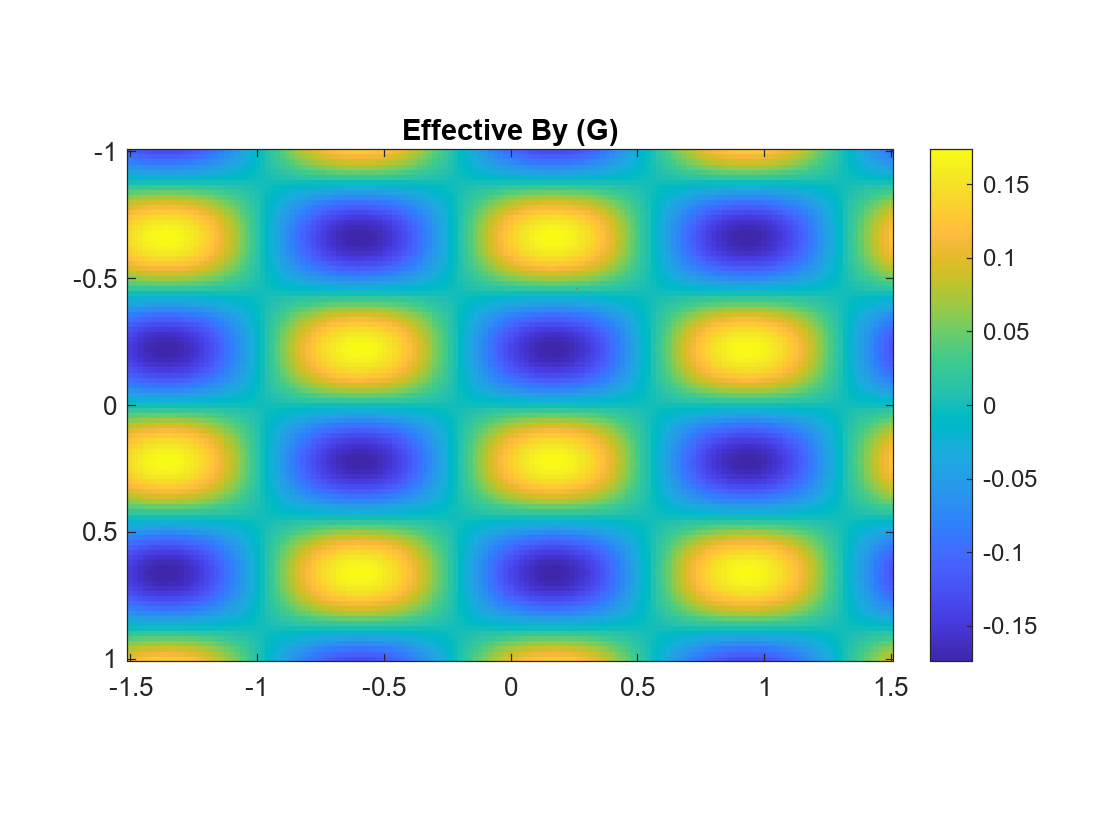


imagesc(YRange,XRange,EffBy)
colorbar
daspect([1 1 1])
title('Effective By (G)')
hold on
scatter(XCenter,YCenter,100,'r',LineWidth=2)
hold off

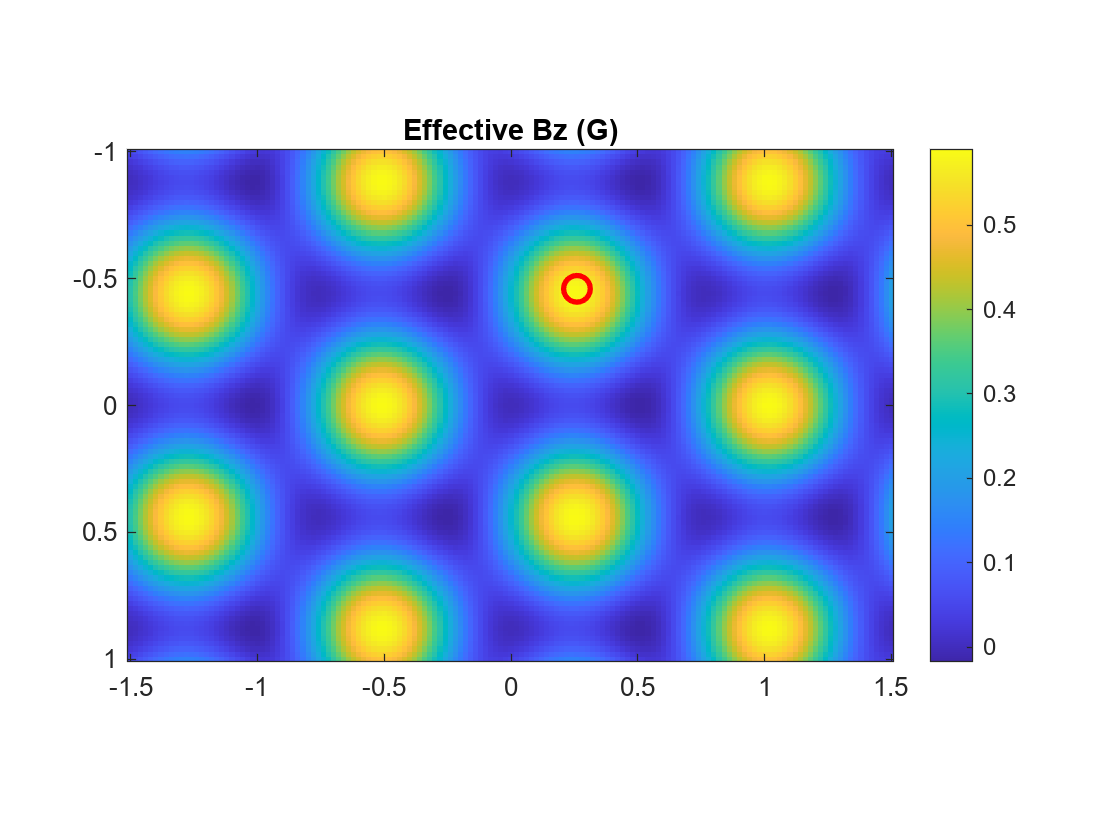


imagesc(YRange,XRange,EffBz)
colorbar
daspect([1 1 1])
title('Effective Bz (G)')
hold on
scatter(XCenter,YCenter,100,'r',LineWidth=2)
hold off

# Characterize Trap

Trap frequency and trap depth

Func = @(x) staticFunc(LatBeam,x);
FreqCenter = fitTrapFreq([0 0 0],Func)

Trap frequency variation across the lattice

FreqSide1 = fitTrapFreq([15 0 0],Func)
FreqSide2 = fitTrapFreq([0 15.5 0],Func)

Potential landscape for ground state F=3 and F=4 atoms


$$H_B = \mu_Bg_{nJ}M_FB$$


kB = 1.3806503e-23;
Func = @(x) vecFunc(LatBeam,x,3,3);
[TrapFreq,FreqVec] = fitTrapFreq([0 0 0],Func)
imagesc(YRange,XRange,reshape(Func([X(:),Y(:),Z(:)]),XSize,YSize)/kB*1e6)
daspect([1 1 1])
colorbar

function Result = staticFunc(Beam,R)
    Result = aNLJ('s',6,0,1/2,Beam.Wave,'Exp')*gaussianFull(Beam,R);
end

function Result = vecFunc(Beam,R,F,mF)
    % 1 Gauss = 1e-4 T
    muB = 9.27400899e-24;
    Factor = sign(F-7/2)/4*muB*1e-4*mF;

    [Intensity,TotPol] = gaussianFull(Beam,R);
    Result = Intensity.*(aNLJ('s',6,0,1/2,Beam.Wave,'Exp')+...
        Factor*aNLJ('v',6,0,1/2,Beam.Wave,'ExpBFict')*vecnorm(1i.*cross(conj(TotPol),TotPol,2),2,2));
end